# Deep learning for classification on the MNIST dataset

## Prepare the dataset

In this example, we will perform image classification using deep learning (from scratch) on the MNIST dataset. The MNIST dataset is a set of handwritten digits categorized 0-9 and is available at [http://yann.lecun.com/exdb/mnist/.](http://yann.lecun.com/exdb/mnist/.)

clear
addpath(genpath(pwd))

The following line will download (if necessary) and prepare the dataset to use in MATLAB.

[imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

Preparing MNIST data...
MNIST data preparation complete.


## Let's look at a few of the images

We will pick a random sampling of the images to take a closer look. Run this section a few times to see different picture montages. "viewDigitMontage" is a custom function found in the "03-HelperFunctions" folder.

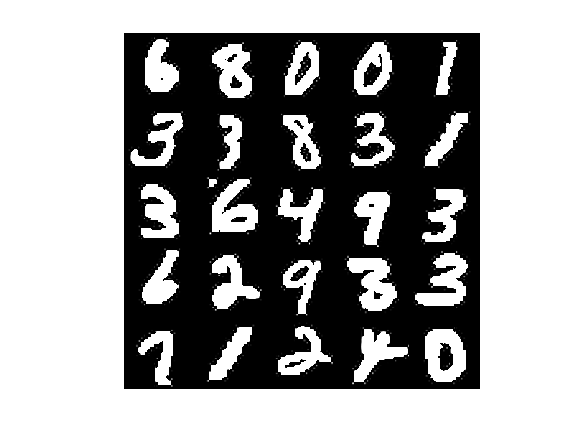

viewDigitMontage(labelsTrain, imgDataTrain)

## How do we classify a digit?

We'll start with the end goal first, and use a model already trained to classify images with MNIST, so we can see what we're trying to achieve.

load MNISTModel

**Note: **You can execute this section of the script multiple times and get a random classification image each time.

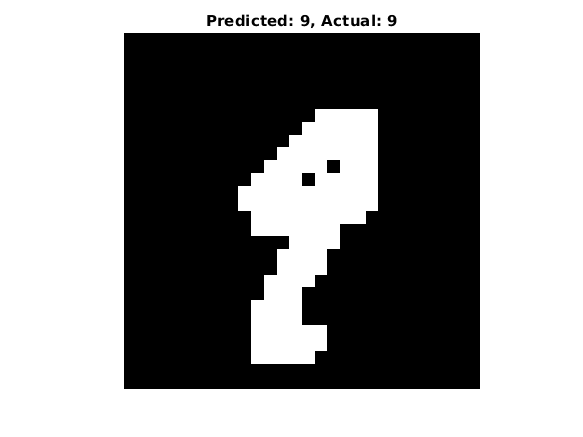

% Predict the class of an image
randIndx = randi(numel(labelsTest));
img = imgDataTest(:,:,1,randIndx);
actualLabel = labelsTest(randIndx);

predictedLabel = classify(net,img);
imshow(img);
title(['Predicted: ' char(predictedLabel) ', Actual: ' char(actualLabel)])

## Prepare the CNN

We found an example of a convolutional neural network (CNN) in the documentation. One of the simplest possible convnets, it contains one convolutional layer, one ReLU, one pooling layer, and one fully connected layer. Let's utilize it as our first attempt at classifying these images.

layers = [  imageInputLayer([28 28 1])
            convolution2dLayer(5,20)
            reluLayer
            maxPooling2dLayer(2, 'Stride', 2)
            fullyConnectedLayer(10)
            softmaxLayer
            classificationLayer   ];

## Deep Network Designer

You can also create networks using the Deep Network Designer. This app provides a drag-and-drop interface, which lets you define layer architecture, layer parameters, and layer connections. After creating a network, you can check it for errors then export it to the workspace. Try to create the network we defined above!

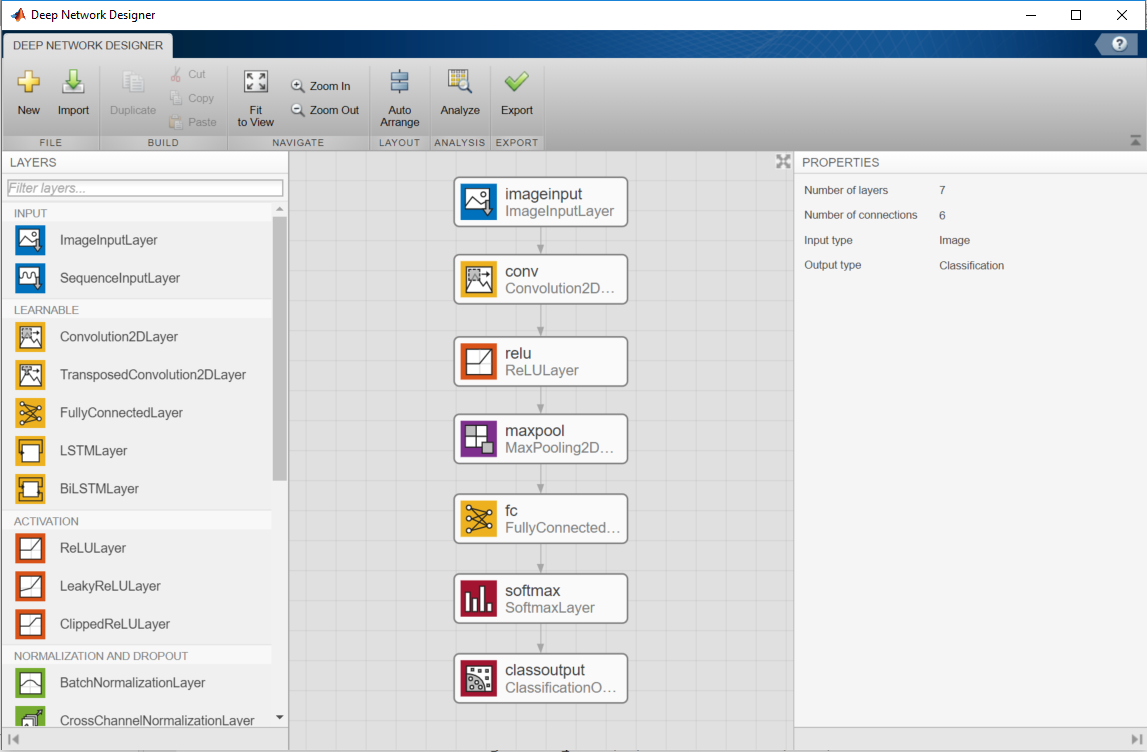

% deepNetworkDesigner

## Attempt 1: Set training options and train the network

Let's use default values and try training this network.

options = trainingOptions( 'sgdm',...
    'Plots', 'training-progress',...
    'MaxEpochs',10);

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 2: Change the learning rate

That didn't work too well. Let's try changing one of the main parameters that affects neural network training: the **learning rate.**

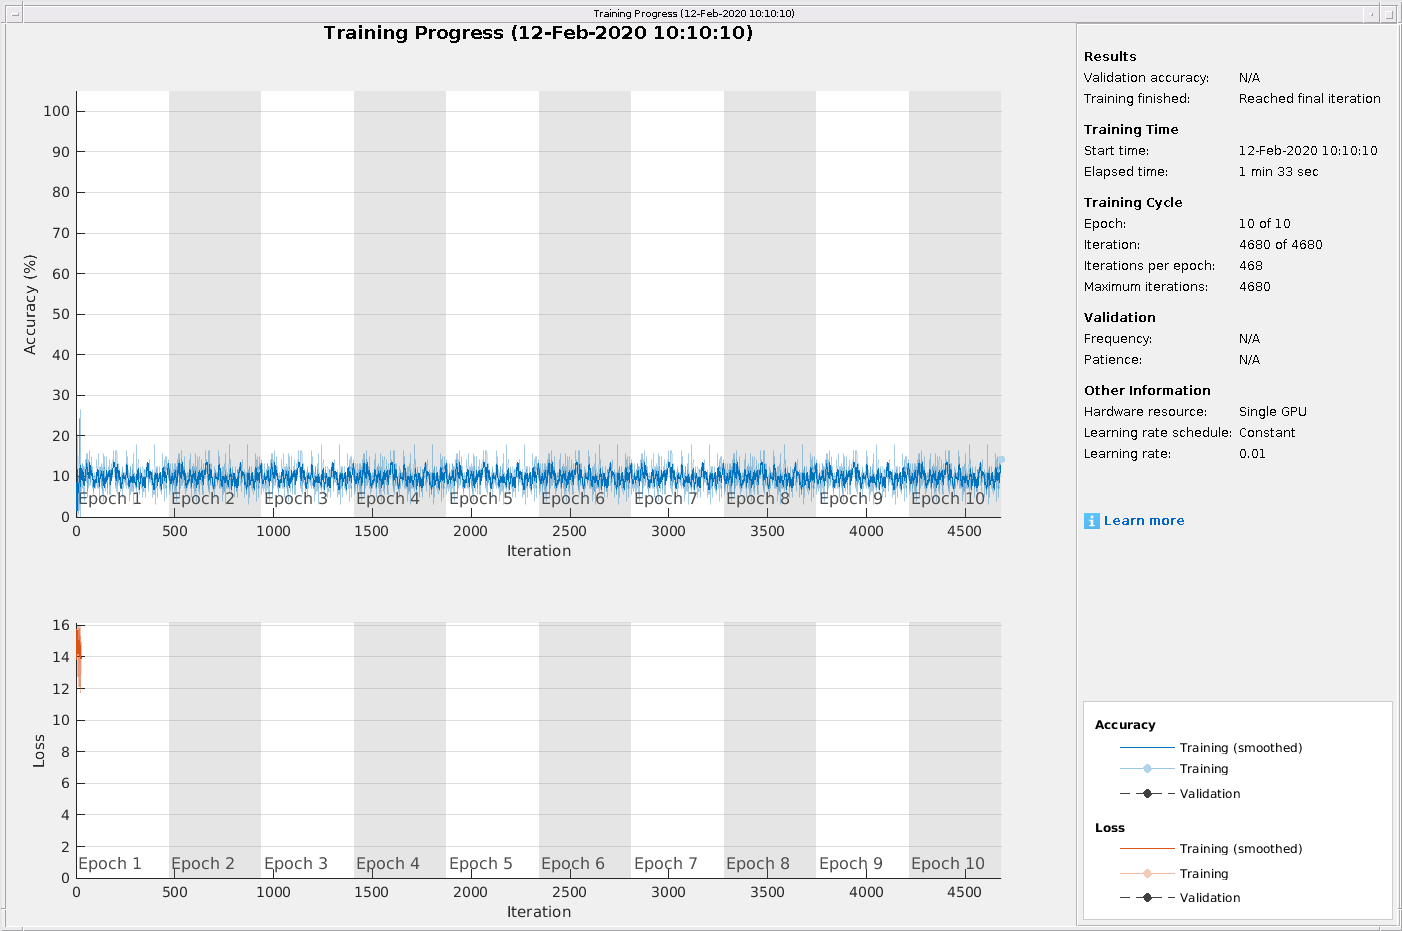

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        8.59% |      13.7930 |          0.0100 |
|       1 |          50 |       00:00:01 |       10.94% |          NaN |          0.0100 |
|       1 |         100 |       00:00:02 |       10.16% |          NaN |          0.0100 |
|       1 |         150 |       00:00:03 |        7.81% |          NaN |          0.0100 |
|       1 |         200 |       00:00:04 |        7.03% |          NaN |          0.0100 |
|       1 |         250 |       00:00:05 |        7.81% |          NaN |          0.0100 |
|       1 |         300 |  

options = trainingOptions('sgdm',...

    'Plots', 'training-progress',...
    'MaxEpochs',10,...
    'InitialLearnRate', 0.0001);

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 3: Change the network architecture

Sometimes, it's not the learning rate that needs changing. Other factors about the model can affect the training as well. Here, instead of playing with hyperparameters such as the learning rate, we can use a more sophisticated CNN in the first place. This one has multiple convolution layers, as well as **batch normalization** layers, which improve the quality and convergence rate of the training.

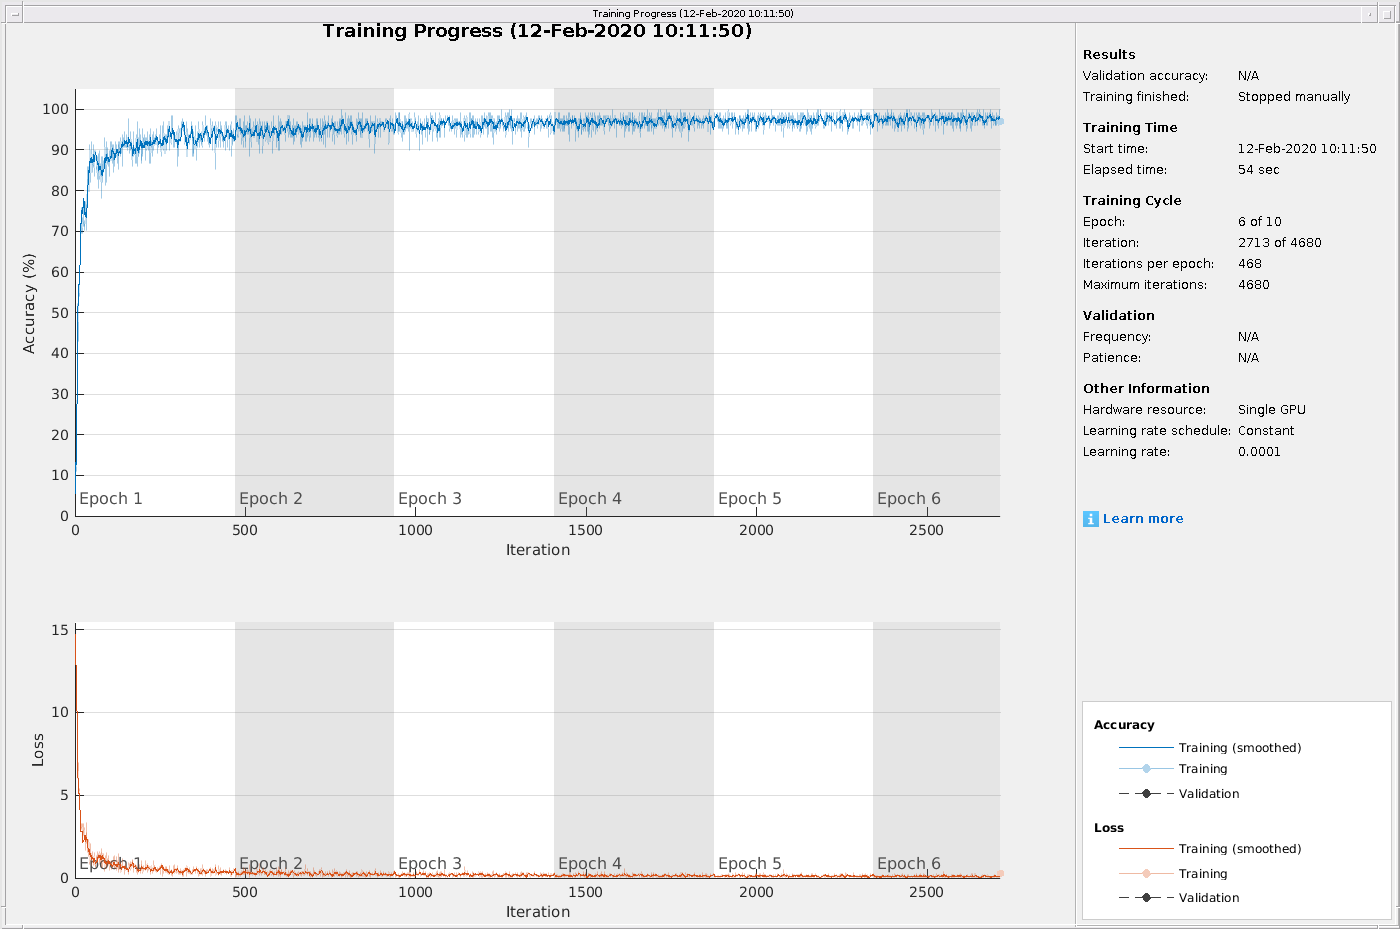

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        5.47% |      14.7233 |      1.0000e-04 |
|       1 |          50 |       00:00:01 |       85.94% |       1.2130 |      1.0000e-04 |
|       1 |         100 |       00:00:02 |       89.84% |       0.4807 |      1.0000e-04 |
|       1 |         150 |       00:00:03 |       90.62% |       0.5006 |      1.0000e-04 |
|       1 |         200 |       00:00:04 |       90.62% |       0.4770 |      1.0000e-04 |
|       1 |         250 |       00:00:05 |       90.62% |       0.7310 |      1.0000e-04 |
|       1 |         300 |  

|       6 |        2400 |       00:00:47 |       98.44% |       0.0176 |      1.0000e-04 |
|       6 |        2450 |       00:00:48 |       98.44% |       0.0430 |      1.0000e-04 |
|       6 |        2500 |       00:00:49 |       97.66% |       0.1031 |      1.0000e-04 |
|       6 |        2550 |       00:00:50 |       98.44% |       0.0545 |      1.0000e-04 |
|       6 |        2600 |       00:00:51 |       99.22% |       0.0257 |      1.0000e-04 |
|       6 |        2650 |       00:00:52 |       97.66% |       0.1090 |      1.0000e-04 |
|       6 |        2700 |       00:00:54 |       97.66% |       0.1377 |      1.0000e-04 |
|       6 |        2713 |       00:00:54 |       96.88% |       0.2563 |      1.0000e-04 |
|========================================================================================|


layers = [

    imageInputLayer([28 28])

    convolution2dLayer(3,16,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,64,'Padding',1)
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];


% define training options as "options"
%[ADD CODE HERE] 

% train the network and save it as "net"
%[ADD CODE HERE] 

## To Do: Classify the test data set

We have a separate set of images in the MNIST dataset set aside specifically for testing. Let's use the test data to test the accuracy of the model we just trained.

% classify test data and save labels as "predLabelsTest"
%[ADD CODE HERE] 

testAccuracy = sum(predLabelsTest == labelsTest) / numel(labelsTest)

Unrecognized function or variable 'predLabelsTest'.

## To Do: Try to classify our own images

Let's try to classify the digits in the "03-HandwrittenDigits" folder

Functions you will need to use

- "imread" for one file

- "imageDatastore" + "read" for multiple files (optional)

- "imshow"

- "preprocessImage" - custom function that will automatically resize the original image

- "classify"

imgPath = fullfile('03-HandwrittenDigits');
ids = imageDatastore(imgPath);

f = figure; 
f.Visible = 'on';

while hasdata(ids)

    %[ADD CODE HERE] 
    
    pause(1)
         
end

*Copyright 2019 The MathWorks, Inc.*